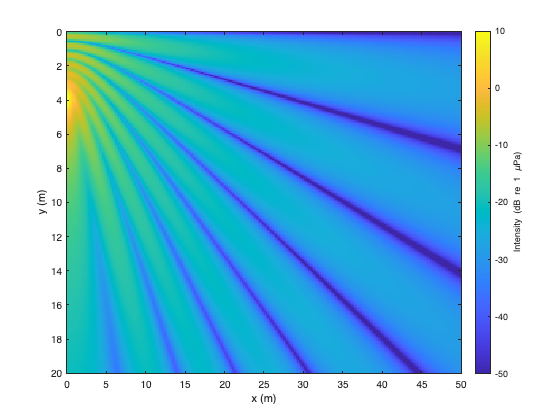

f = 1380; % frequency in Hz
d = 4; % Source Depth
MaxRange = 50;
c = 1500 ; % Speed of sound (m/s)


dmax = 10; % max depth of source
Lx = MaxRange; % horizontal extent of calculation
Ly = 2*dmax; % vertical extent of calculation
Nx = 250; % Number of points in horizontal calculation
Ny = Nx;
x = linspace(0,Lx,Nx);
y = linspace(0,Ly,Ny);

SL = 0; % SL is 0 dB
A_SL = 10^(SL/20); % pressure amplitude of source (microPascal)

[X,Y] = meshgrid(x,y);

r1 = sqrt(X.^2 + (Y-d).^2); % Range from source
r2 = sqrt(X.^2 + (Y+d).^2); % Range from virtual source

p1 = A_SL.*exp(1i*2*pi*f*r1/c)./r1; % Pressure due to source
p2 = -A_SL.*exp(1i*2*pi*f*r2/c)./r2; % Pressure due to virtual source
p = p1 + p2; % Coherent sum of source and virtual source

plotType = 1;

if plotType == 0
    imagesc(x,y,real(p)*sqrt(2)) % Plot the pressure
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Pressure (\muPa)';

elseif plotType == 1
    imagesc(x,y,20*log10(abs(p))) % Plot the intensity
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Intensity (dB re 1 \muPa)';
    a.CLim = [-50 10];
else 

    imagesc(x,y,angle(p)) % Plot the phase of the pressure
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Phase (radians)';

end


c/(2*f) 

ans = 0.5435

Pulse propagation

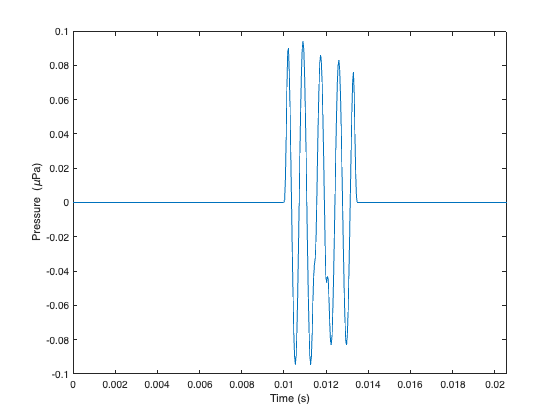

recDepth = 4;
recRange = 15;


rec1R = sqrt(recRange.^2 + (recDepth-d).^2); % Range from source
rec2R = sqrt(recRange.^2 + (recDepth+d).^2); % Range from virtual source

ts1 = rec1R/c;
ts2 = rec2R/c;

pr1 = A_SL.*exp(1i*2*pi*f*rec1R/c)./rec1R; % Pressure due to source
pr2 = -A_SL.*exp(1i*2*pi*f*rec2R/c)./rec2R; % Pressure due to virtual source

intensityCW = 20*log10(abs(pr1 + pr2));

dt = (1/f)/20; % time increment for calculation (T/10)
t1 = [0:dt:ts2*3]; % time array
maxTime = t1(end);
DefaultTime = [0 maxTime]; % Default for the plots
% The transmitted pulse is a continous wave signal transmitted for a
% certain number of periods defined by the variable PulseWidth.
PulseWidth = 3; 
DisplayTimeStart = 0; % Define the time axis of the plots
DisplayTimeEnd = 0.41716000000000003;
TimeRange = [DisplayTimeStart DisplayTimeEnd];
tau = PulseWidth/f; % Time from start to end of the transmitted pulse

% Note that the transmitted pulse is a CW signal with a 100% cosine taper
% (tukey window). The shading follows the equation, 1 - cos(t/T), where T
% is the period of the transmitted CW signal.


Output_pulse = CW_pulse_propagation(pr1,t1,ts1,f,tau,0.2) + ...
    CW_pulse_propagation(pr2,t1,ts2,f,tau,0.2);

%% Plot the pressure time series

figure(3)
plot(t1,real(Output_pulse).*sqrt(2)*10.^(SL/20))

a2 = gca;
a2.XLabel.String = 'Time (s)';
a2.YLabel.String = 'Pressure (\muPa)';
a2.XLim = TimeRange;

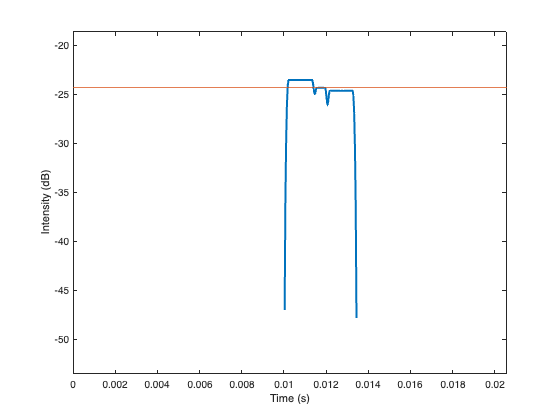

%% Plot the Intensity Time Series

figure(4)
plot(t1,20*log10(abs(Output_pulse))+SL,...
    'LineWidth',2)

a3 = gca;

maxIntensity = max(20*log10(abs(Output_pulse))) + SL;

hold on
line([0 t1(end)],intensityCW.*[1 1])
hold off


a3.YLim = maxIntensity + [-30 5];
a3.XLim = TimeRange;
a3.XLabel.String = 'Time (s)';
a3.YLabel.String = 'Intensity (dB)';